## Dynamic Channel Allocation in Mobile WIRT in-X 6G Subnetworks

                             Author: Ramoni Adeogun [AAU, 2021]

## Performance comparison of distributed and centralized algorithms

- Random selection: select from channel list randomly when condition become worst

- Greedy: select the best channel if condition on current channel becomes bad

- minSINR: select worst channel satisfying SINR requirement

- Nearest neighbour conflict avoidance (NNCA): select a channel not in use by nearest neighbours

- GreedyR: avoid the best channel if there is a conflict with nearest neighbours

- NNCAS: NNCA with signalling among cells

## House keeping and screen splash

clc; clear;
disp('%==================================================================%')

%==================================================================%


disp('Dynamic Channel Allocation in Mobile WIRT in-X 6G Subnetworks')

Dynamic Channel Allocation in Mobile WIRT in-X 6G Subnetworks


disp('===================================================================')

rng('default');
set(groot,'defaultLineLineWidth',2)

## Environment and Simulation settings

envConstant = envConstants();
numSim = ceil(envConstant.simT/envConstant.transTime);
WIRT = GenerateWIRTNetwork(envConstant,numSim,'nfreeway');
WIRT.envConstant = envConstant;
numE = envConstant.numCell*envConstant.numDev;
outageTarget = envConstant.outageTarget;
numWarmUp = envConstant.warmUp/envConstant.sampTime;
initOption = 'nrandom';
numSensingSteps = envConstant.sampTime/envConstant.transTime;
numSignallingSteps = envConstant.sigTime/envConstant.transTime;
nCDIndx = 2;
N = envConstant.numCell;
M = envConstant.numGroups;
SINRth = envConstant.SINRvec(nCDIndx);
numAlgo = length(envConstant.algo);

## Memory preallocation for speed (store actions for analysing switching frequency etc)

action_hist = zeros(length(envConstant.algo),envConstant.numCell,envConstant.numMap*numSim);

## Initialization: Initialize all algorithms using either random selection or channel assignment based on CGC. 

interMat = (squeeze(WIRT.rxPower(1:envConstant.numCell,1:envConstant.numCell,1)));
action.CGC = centralizedColoring(abs(interMat),envConstant.numGroups,'greedy'); 

if strcmp(initOption, 'random')
    action.NNCA = WIRT.channel;
    action.Greedy = WIRT.channel;
    action.GreedyR = WIRT.channel;
    action.minSINR = WIRT.channel;
    action.NNCAS = WIRT.channel;
    action.RDM = WIRT.channel;
else
    action.NNCA = action.CGC;
    action.Greedy = action.CGC;
    action.GreedyR = action.CGC;
    action.minSINR = action.CGC;
    action.NNCAS = action.CGC;
    action.RDM = action.CGC;
end
for indxAlgo = 1:length(envConstant.algo)
    for sIndx = 1:envConstant.numCell
        algo(indxAlgo).IndxI{sIndx} = [];
    end
end


## Loop over all time steps

switch_indicator = 1;
mapCt = 1;
for stepCt = 1:envConstant.numMap*numSim
    if mod(stepCt,numSim) == 1 && stepCt ~= 1
        mapCt = 1;
        WIRT = GenerateWIRTNetwork(envConstant,numSim,'nfreeway');
        WIRT.envConstant = envConstant;
        interMat = (squeeze(WIRT.rxPower(1:envConstant.numCell,1:envConstant.numCell,1)));
        action.CGC = centralizedColoring(abs(interMat),envConstant.numGroups,'greedy'); 
        if strcmp(initOption, 'random')
            action.NNCA = WIRT.channel;
            action.Greedy = WIRT.channel;
            action.GreedyR = WIRT.channel;
            action.minSINR = WIRT.channel;
            action.NNCAS = WIRT.channel;
            action.RDM = WIRT.channel;
        else
            action.NNCA = action.CGC;
            action.Greedy = action.CGC;
            action.GreedyR = action.CGC;
            action.minSINR = action.CGC;
            action.NNCAS = action.CGC;
            action.RDM = action.CGC;
        end
        disp('Environment updated')
    end
    switch_delay = randi(envConstant.maxDelay,envConstant.numCell,1);
    % Calculate uplink/downlink SINR and aggregate interference power
    
   for indxAlgo = 1:length(envConstant.algo)
        if indxAlgo == 1
            [algo(indxAlgo).upSINR,algo(indxAlgo).downSINR,algo(indxAlgo).intPow,~] = computeSINRAllRep(WIRT,...
                action.RDM,mapCt,algo(indxAlgo).IndxI,'nonrandom');
            algo(indxAlgo).upSINRCC = cumsum(algo(indxAlgo).upSINR,3);
            algo(indxAlgo).downSINRCC = cumsum(algo(indxAlgo).downSINR,3);
            algo(indxAlgo).minSINR = min([(min(algo(indxAlgo).upSINRCC(:,:,1),[],2)) (min(algo(indxAlgo).downSINRCC(:,:,1),[],2))],[],2);
        elseif indxAlgo == 2
            [algo(indxAlgo).upSINR,algo(indxAlgo).downSINR,algo(indxAlgo).intPow,~] = computeSINRAllRep(WIRT,...
                action.Greedy,mapCt,algo(indxAlgo).IndxI,'nonrandom');
            algo(indxAlgo).upSINRCC = cumsum(algo(indxAlgo).upSINR,3);
            algo(indxAlgo).downSINRCC = cumsum(algo(indxAlgo).downSINR,3);
            algo(indxAlgo).minSINR = min([(min(algo(indxAlgo).upSINRCC(:,:,1),[],2)) (min(algo(indxAlgo).downSINRCC(:,:,1),[],2))],[],2);
        elseif indxAlgo == 3
            [algo(indxAlgo).upSINR,algo(indxAlgo).downSINR,algo(indxAlgo).intPow,algo(indxAlgo).IndxI] = computeSINRAllRep(WIRT,...
                action.NNCA,mapCt,algo(indxAlgo).IndxI,'nonrandom');
            algo(indxAlgo).upSINRCC = cumsum(algo(indxAlgo).upSINR,3);
            algo(indxAlgo).downSINRCC = cumsum(algo(indxAlgo).downSINR,3);
            algo(indxAlgo).minSINR = min([(min(algo(indxAlgo).upSINRCC(:,:,1),[],2)) (min(algo(indxAlgo).downSINRCC(:,:,1),[],2))],[],2);
        elseif indxAlgo == 4
            [algo(indxAlgo).upSINR,algo(indxAlgo).downSINR,algo(indxAlgo).intPow,algo(indxAlgo).IndxI] = computeSINRAllRep(WIRT,...
                action.GreedyR,mapCt,algo(indxAlgo).IndxI,'nonrandom');
            algo(indxAlgo).upSINRCC = cumsum(algo(indxAlgo).upSINR,3);
            algo(indxAlgo).downSINRCC = cumsum(algo(indxAlgo).downSINR,3);
            algo(indxAlgo).minSINR = min([(min(algo(indxAlgo).upSINRCC(:,:,1),[],2)) (min(algo(indxAlgo).downSINRCC(:,:,1),[],2))],[],2);
        elseif indxAlgo == 5
            [algo(indxAlgo).upSINR,algo(indxAlgo).downSINR,algo(indxAlgo).intPow,~] = computeSINRAllRep(WIRT,...
                action.NNCAS,mapCt,algo(indxAlgo).IndxI,'nonrandom');
            algo(indxAlgo).upSINRCC = cumsum(algo(indxAlgo).upSINR,3);
            algo(indxAlgo).downSINRCC = cumsum(algo(indxAlgo).downSINR,3);
            algo(indxAlgo).minSINR = min([(min(algo(indxAlgo).upSINRCC(:,:,1),[],2)) (min(algo(indxAlgo).downSINRCC(:,:,1),[],2))],[],2);
        elseif indxAlgo == 6
            [algo(indxAlgo).upSINR,algo(indxAlgo).downSINR,algo(indxAlgo).intPow,~] = computeSINRAllRep(WIRT,...
                action.CGC,mapCt,algo(indxAlgo).IndxI,'nonrandom');
            algo(indxAlgo).upSINRCC = cumsum(algo(indxAlgo).upSINR,3);
            algo(indxAlgo).downSINRCC = cumsum(algo(indxAlgo).downSINR,3);
            algo(indxAlgo).minSINR = min([(min(algo(indxAlgo).upSINRCC(:,:,1),[],2)) (min(algo(indxAlgo).downSINRCC(:,:,1),[],2))],[],2);
        end
    end
    % Compute estimate of the number of failed loops
    for nC = 1:envConstant.numBWConf
        Pmap = WIRT.envConstant.outageMap.Pout{16-(nC)+1}; 
        Smap = WIRT.envConstant.outageMap.SINR{16-(nC)+1};
        for indxAlgo = 1:length(envConstant.algo)
            uplinkPoutCC = probMapping(Pmap,Smap,10*log10(algo(indxAlgo).upSINRCC));
            downlinkPoutCC = probMapping(Pmap,Smap,10*log10(algo(indxAlgo).downSINRCC));
            upIndxCC = find(uplinkPoutCC>outageTarget);
            downIndxCC = find(downlinkPoutCC>outageTarget);
            nSDevCC(indxAlgo,nC) = numel(ismember(upIndxCC,downIndxCC));
        end
    end
    perfResult(:,:,stepCt) = nSDevCC;
    action_hist(1,:,stepCt) = action.RDM;
    action_hist(2,:,stepCt) = action.Greedy;
    action_hist(5,:,stepCt) = action.NNCAS;
    action_hist(3,:,stepCt) = action.NNCA;
    action_hist(4,:,stepCt) = action.GreedyR;
    action_hist(6,:,stepCt) = action.CGC;
    % Check sensing interval condition and begin channel selection
    % operations
    if switch_indicator >= envConstant.maxDelay
        switch_indicator = 1;
    end
    if mapCt >= numSensingSteps
%         gwloc = squeeze(WIRT.gwLoc(:,:,mapCt)).';
%         gwdist = pdist2(gwloc,gwloc);
%         D = processRank(gwdist,algo(5).intPow);
        interMat = (squeeze(WIRT.rxPower(1:envConstant.numCell,1:envConstant.numCell,mapCt)));
        for indxAlgo = 1:length(envConstant.algo)
            for indxCell = 1:N
                if algo(indxAlgo).minSINR(indxCell) <= SINRth && switch_delay(indxCell) == switch_indicator
                    if indxAlgo == 1
                        action.RDM(indxCell) = randi(M,1);
                    elseif indxAlgo == 2
                        [~,action.Greedy(indxCell)] = min(algo(indxAlgo).intPow(indxCell,:));
                    elseif indxAlgo == 3
                            action.NNCA(indxCell) = nearestNeighbourAvoidance(squeeze(interMat(indxCell,:)),...
                                action.NNCA,envConstant.numGroups,'nonaggregate');   
                    elseif indxAlgo == 4
%                         action.GreedyR(indxCell) = greedyRankExchange(squeeze(D(indxCell,:,:)));
                          [~,action.GreedyR(indxCell)] = min(algo(indxAlgo).intPow(indxCell,:));
                    elseif indxAlgo == 5
                        action.NNCAS(indxCell) = nearestNeighbourAvoidance(squeeze(interMat(indxCell,:)),...
                            action.NNCAS,envConstant.numGroups,'nonaggregate');
                         
                    end
                                    
                end
                
            end
        end
%         for indxCell = 1:N
%             action.NNCAS(indxCell) = nearestNeighbourAvoidance(squeeze(interMat(indxCell,:)),...
%                             action.NNCAS,envConstant.numGroups,'nonaggregate');
%         end
                        
        action.CGC = centralizedColoring(abs(interMat),envConstant.numGroups,'greedy'); 
        switch_indicator = switch_indicator + 1;
    end
    mapCt = mapCt +1;
    if mod(stepCt,100) == 0
        disp(['Number of steps completed:', num2str(stepCt)]);  
    end
       
end 

Number of steps completed:100
Number of steps completed:200
Number of steps completed:300
Number of steps completed:400
Number of steps completed:500
Number of steps completed:600
Number of steps completed:700
Number of steps completed:800
Number of steps completed:900
Number of steps completed:1000
Number of steps completed:1100
Number of steps completed:1200
Number of steps completed:1300
Number of steps completed:1400
Number of steps completed:1500
Number of steps completed:1600
Number of steps completed:1700
Number of steps completed:1800
Number of steps completed:1900
Number of steps completed:2000
Number of steps completed:2100
Number of steps completed:2200
Number of steps completed:2300
Number of steps completed:2400
Number of steps completed:2500
Number of steps completed:2600
Number of steps completed:2700
Number of steps completed:2800
Number of steps completed:2900
Number of steps completed:3000
Number of steps completed:3100
Number of steps completed:3200
Number of steps c

## Compute PLF

%perfResult(:,:,[1:10 20000:20020 40000:40020 60000 60020 80000 80020 100000 100020  ]) = [];
PLF = mean(perfResult,3)/numE;

## Plotting results

linestyle = {'-bo','-rs','-gd','--rs','--gd','-kd'}

linestyle = 1×6 cell array
    {'-bo'}    {'-rs'}    {'-gd'}    {'--rs'}    {'--gd'}    {'-kd'}


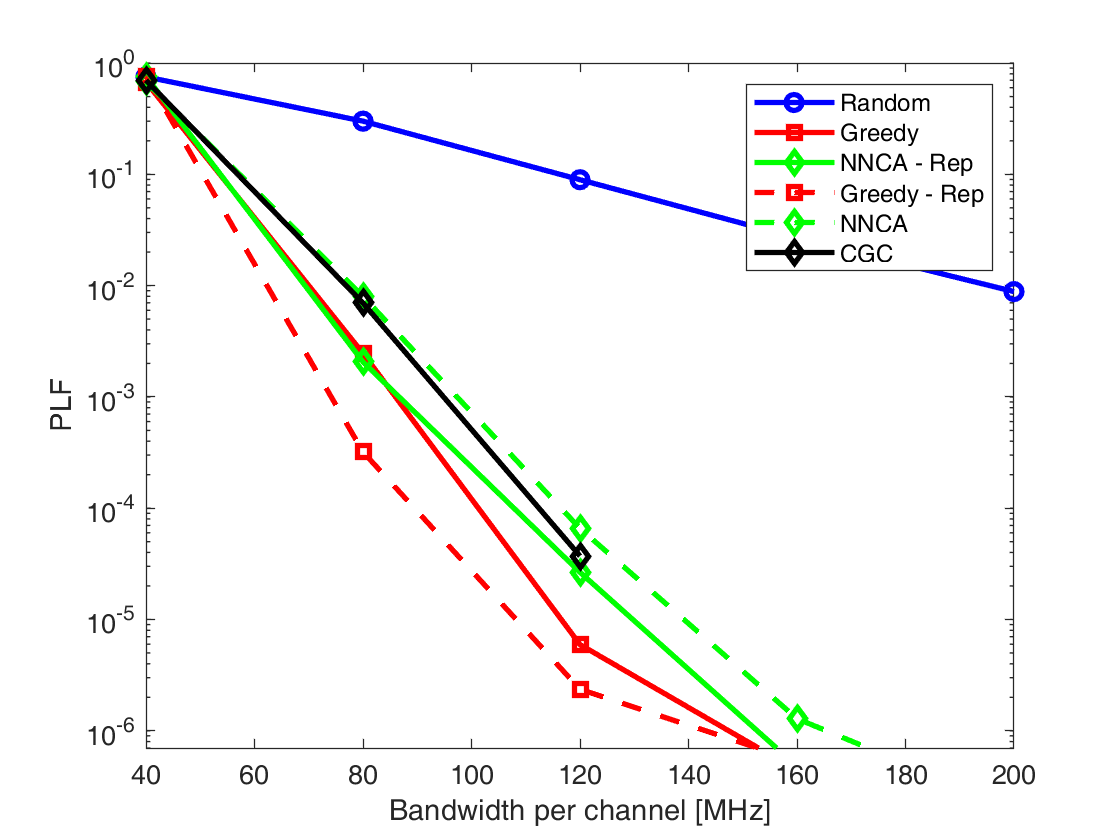

indBW = 1:envConstant.numBWConf;
tt= figure(); 
for plIndx = 1:length(envConstant.algo)
    semilogy(indBW*40,PLF(plIndx,:),linestyle{plIndx},'linewidth',2,'DisplayName',envConstant.algo{plIndx});  hold on
end
xlabel('Bandwidth per channel [MHz]')
ylabel('PLF');
ylim([7e-7 1]);
xlim([40 envConstant.numBWConf*40]);
legend show
hold off

%savefig(tt,'PLFResultandMCSnn')
%%exportgraphics(tt,'PLFResult.pdf')


## Plot switching rate, CSF, etc

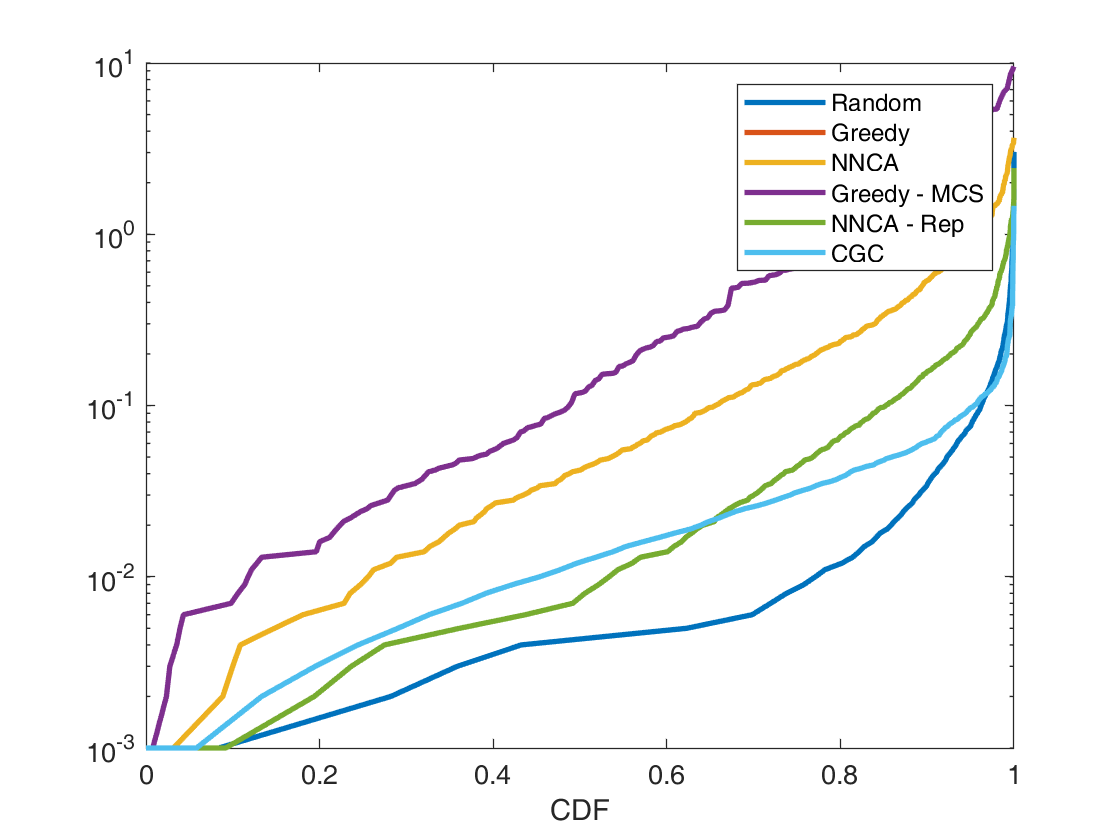

%calculate channel frequency
for plIndx = 1:length(envConstant.algo)
    CSF(plIndx) = numel(find(diff(squeeze(action_hist(plIndx,:,:)),1,2)~=0))/numel(squeeze(action_hist(plIndx,:,:)));
end
% calculate channel usage fairness
for plIndx = 1:length(envConstant.algo)
    for cIndx = 1:envConstant.numGroups
        CUF(plIndx,cIndx) = numel(find(squeeze(action_hist(plIndx,:,:)) == cIndx))/numel(squeeze(action_hist(plIndx,:,:)));
    end
end
% calculate time between channel switching 
for plIndx = 1:length(envConstant.algo)
    CC = [];
    for sIndx = 1:envConstant.numCell
        CC= [CC diff(find(diff(squeeze(action_hist(plIndx,sIndx,:)))~=0))'];
    end
    TBC{plIndx} = CC*envConstant.transTime;
end
for plIndx = 1:length(envConstant.algo)
    [f{plIndx} , x{plIndx} ] = ecdf(TBC{plIndx});
end

cc= figure(); 
for plIndx = 1:length(envConstant.algo)
    semilogy(f{plIndx},x{plIndx},'linewidth',2,'DisplayName',envConstant.algo{plIndx});  hold on
end
hold off
legend show
xlabel('CDF')